## Find steady states for non-ratiometric and ratiometric situations

Ra: Active receptor

Ri: Inactive receptor

Total receptor R = Ra+Ri

In a linear gradient, where x goes from 0 to 5 microns:

Ra = R*(f0 + m*x) -- where f0<0.5

 Ri =R*(1 - f0 - m*x)

m = (1-2*f0)/5 -- since 5 microns is width of the cell

Ga: Active G protein

Gi : inactive G protein

Gi = G - Ga

Activation: Gi to Ga at kp*Ra*Gi

Inactivation: Ga to Gi at km*Ga (non-ratiometric) OR kr*Ri*Ga (ratiometric)

clear all
syms R_a R_i R f_0 m x G_a G_i G k_p k_m k_r GaNR GaR beta


NRSS = k_p*R_a*G_i == k_m*G_a;
RSS = k_p*R_a*G_i == k_r*R_i*G_a;

G_i = G - G_a;
m=(1-2*f_0)/5;
R_a = R*(f_0 + m*x);
R_i=R*(1 - f_0 - m*x);

%solve steady state for non-ratiometric case
NRSS = k_p*R_a*G_i == k_m*G_a;
GaNR = solve(NRSS,G_a);
GaNR = subs(GaNR,k_m, 0.5*R*k_r);
GaNR = subs(GaNR,k_p,k_r/beta)

$$GaNR = \frac{G\,R\,k_{r}\,\left(f_{0}-x\,\left(\frac{2\,f_{0}}{5}-\frac{1}{5}\right)\right)}{\beta \,\left(\frac{R\,k_{r}}{2}+\frac{R\,k_{r}\,\left(f_{0}-x\,\left(\frac{2\,f_{0}}{5}-\frac{1}{5}\right)\right)}{\beta }\right)}$$

%disp(latex(GaNR))

%solve steady state for ratiometric case
RSS = k_p*R_a*G_i == k_r*R_i*G_a;
GaR = solve(RSS,G_a);
GaR = subs(GaR,k_p,k_r/beta)

$$GaR = \frac{G\,R\,k_{r}\,\left(f_{0}-x\,\left(\frac{2\,f_{0}}{5}-\frac{1}{5}\right)\right)}{\beta \,\left(R\,k_{r}\,\left(x\,\left(\frac{2\,f_{0}}{5}-\frac{1}{5}\right)-f_{0}+1\right)+\frac{R\,k_{r}\,\left(f_{0}-x\,\left(\frac{2\,f_{0}}{5}-\frac{1}{5}\right)\right)}{\beta }\right)}$$

%disp(latex(GaR))

%Find difference between signal at x=5 and x=0
GaNR5 = subs(GaNR,x,5);
GaNR0 = subs(GaNR,x,0);
deltaGaNR = GaNR5 - GaNR0

$$deltaGaNR = -\frac{G\,R\,k_{r}\,\left(f_{0}-1\right)}{\beta \,\left(\frac{R\,k_{r}}{2}-\frac{R\,k_{r}\,\left(f_{0}-1\right)}{\beta }\right)}-\frac{G\,R\,f_{0}\,k_{r}}{\beta \,\left(\frac{R\,k_{r}}{2}+\frac{R\,f_{0}\,k_{r}}{\beta }\right)}$$

%disp(latex(deltaGaNR))

GaR5 = subs(GaR,x,5);
GaR0 = subs(GaR,x,0);
deltaGaR = GaR5 - GaR0

$$deltaGaR = \frac{G\,R\,f_{0}\,k_{r}}{\beta \,\left(R\,k_{r}\,\left(f_{0}-1\right)-\frac{R\,f_{0}\,k_{r}}{\beta }\right)}-\frac{G\,R\,k_{r}\,\left(f_{0}-1\right)}{\beta \,\left(R\,f_{0}\,k_{r}-\frac{R\,k_{r}\,\left(f_{0}-1\right)}{\beta }\right)}$$

%disp(latex(deltaGaR))

%Find ratio of the differences

%express everything in terms of kr
SR = deltaGaR/deltaGaNR

$$SR = \begin{array}{l} -\frac{\frac{G\,R\,f_{0}\,k_{r}}{\beta \,\left(R\,k_{r}\,\left(f_{0}-1\right)-\frac{R\,f_{0}\,k_{r}}{\beta }\right)}-\frac{\sigma_{2}}{\beta \,\left(R\,f_{0}\,k_{r}-\sigma_{1}\right)}}{\frac{\sigma_{2}}{\beta \,\left(\frac{R\,k_{r}}{2}-\sigma_{1}\right)}+\frac{G\,R\,f_{0}\,k_{r}}{\beta \,\left(\frac{R\,k_{r}}{2}+\frac{R\,f_{0}\,k_{r}}{\beta }\right)}}\\ \mathrm{where}\\ \sigma_{1}=\frac{R\,k_{r}\,\left(f_{0}-1\right)}{\beta }\\ \sigma_{2}=G\,R\,k_{r}\,\left(f_{0}-1\right) \end{array}$$

%disp(latex(SR))
%SR = subs(SR,k_m, 0.5*R*k_r);
%SR = subs(SR,k_p,k_r/beta);

%SR = subs(SR,f0,0.3);
%SR = subs(SR,a,4);

SR = simplify(SR)

$$SR = \frac{\beta^{2}+2\,\beta -4\,{f_{0}}^{2}+4\,f_{0}}{2\,\left(-\beta^{2}\,{f_{0}}^{2}+\beta^{2}\,f_{0}+2\,\beta \,{f_{0}}^{2}-2\,\beta \,f_{0}+\beta -{f_{0}}^{2}+f_{0}\right)}$$

%disp(latex(SR))

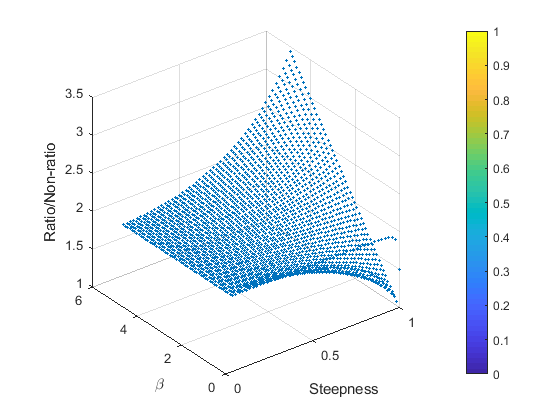

%convert to numerical form and plot some graphs

%see what the signal ration for rationmetric/nonratiometrix sensing looks
%like for a range of different parameters.

f_0 = [0.001:0.01:0.49]; %find a range for f_0
beta = [0.001:0.1:5]'; % find a range for a
nf = numel(f_0); %these parameters are meant to define a 2d matrix
na = numel(beta);

f_0 = repmat(f_0,[na 1]);
beta = repmat(beta,[1 nf]);

SR = (beta.^2 + 2*beta - 4*f_0.^2 + 4*f_0)./(2*(- beta.^2.*f_0.^2 + beta.^2.*f_0 + 2*beta.*f_0.^2 - 2*beta.*f_0 + beta - f_0.^2 + f_0));

%convert f_0 to steepness

steepness = (1-2*f_0);

scatter3(steepness(:),beta(:),SR(:),5,'filled')
colorbar
xlabel('Steepness'); ylabel('\beta'); zlabel('Ratio/Non-ratio');
  set(gcf ,'renderer' ,'painters') %do this or matlab will fucking fail to generate a vector graphic

axis square

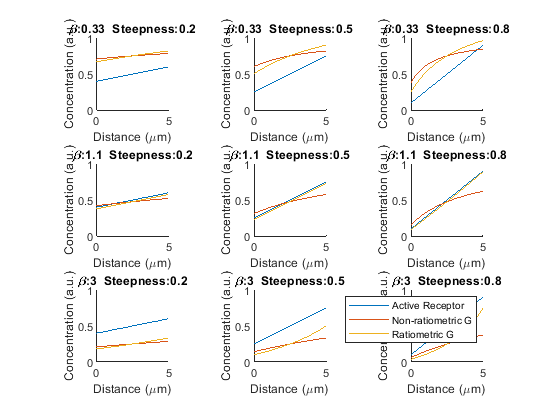

%% plot G protein gradients
close all
betas = [0.33 1.1 3];
f_0s = [ 0.40 0.25 0.1];

plotcount = 0;

for ii = 1:3
    for jj = 1:3
        
        
        x = [0:0.2:5];
        f_0 = f_0s(jj);
        m=(1-2*f_0)/5;
        steepness = (1-2*f_0);
        R = 1; G = 1;
        R_a = R*(f_0 + m*x);
        R_i=R*(1 - f_0 - m*x);
        k_r = 1;
        beta = betas(ii);
        
        
        GaNR = (G.*R.*k_r.*(f_0 - x.*((2.*f_0)./5 - 1./5)))./(beta.*((R.*k_r)./2 + (R.*k_r.*(f_0 - x.*((2.*f_0)./5 - 1./5)))./beta));
        
        GaR = (G.*R.*k_r.*(f_0 - x.*((2.*f_0)./5 - 1./5)))./(beta.*(R.*k_r.*(x.*((2.*f_0)./5 - 1./5) - f_0 + 1) + (R.*k_r.*(f_0 - x.*((2.*f_0)./5 - 1./5)))./beta));
        
        
        
        plotcount = plotcount+1;
        subplot( 3,3,plotcount)
        hold on
        
        title(['\beta:',num2str(beta),'  Steepness:',num2str(steepness)   ])
        plot(x,R_a)
        plot(x,GaNR)
        
        plot(x,GaR)
        ylim([0 1])
        xlim([0 5])
        
        xlabel('Distance (\mum)')
        ylabel('Concentration (a.u.)')
        
        
        axis square
        
    end
end


legend('Active Receptor','Non-ratiometric G','Ratiometric G')